MECE6397: Learning-Based Control

# Homework 4: Learning Dynamical Systems in Real Time

Lecturer: Marzia Cescon

In Homework 1 we have reviewed two common classes of mathematical models used to describe the behavior of a dynamic system from first-principles. This represented an analytical approach to the construction of a model. In many cases the processes are so complex that it is simply not possible to obtain reasonable models using only physical insights. An alternative way, then, to obtain mathematical representations of systems is offered by system identification. In this approach, experiments are performed on the system by exciting its dynamics in order to collect data. A model, then, is fitted to the generated data by assigning suitable numerical values to its parameters. Often, it happens that a model based on first-principles contains a number of unknown parameters. Identification methods can be applied to estimate the unknown parameters. 

In this homework we will study a method to update the model's parameter estimates obtained with system **identification in real-time**. For more details on the methods, check [1], [2].

## 1. Linear regression models

Let us consider the model structure $M\;$given by the difference equation: 


$$y\left(t\right)+a\;y\left(t-1\right)=b\;u\left(t-1\right)+\varepsilon \left(t\right)$$
 

where $t\in \mathbb{R}$ indicates time, $y\left(t\right)$ is the observed output variable, $u\left(t\right)$is the input variable and $\varepsilon \left(t\right)$ is a disturbance term. The vector of parameters is defined as $\theta ={\left\lbrack a\;\;b\right\rbrack }^{\top } \ldotp$ For a given dataset $\left\lbrace u\left(1\right)\;y\left(1\right),u\left(2\right)\;y\left(2\right),\cdots ,u\left(N\right)\;y\left(N\right)\right\rbrace ,$ the term $\left\lbrace \varepsilon \left(t\right)\right\rbrace$can be regarded as a function of the parameter vector. To see this, let us rewrite the difference equation as:


$$\varepsilon \left(t\right)=y\left(t\right)-\left(-y\left(t-1\right)\;u\left(t-1\right)\right)\cdot \theta =y\left(t\right)-\varphi {\;}^{\top } \;\left(t\right)\cdot \theta$$
 

where the vector $\varphi \left(\cdot \right)$ was introduced to contain the so-called *regression variables* or regressors. The parameter vector $\theta$ can be estimated in such a way that it minimizes the *sum of squared* equation errors. That is, introducing the *least-squares loss function* $V\left(\theta ,t\right)=\frac{1}{2}\sum_{t=1}^N \varepsilon^2 \left(t\right)$ $\Longrightarrow$ $\hat{\theta} = \text{arg} \min_{\theta} V(\theta,t
)$. Since the measured variable $y\left(t\right)$ is linear in the parameters, and the least-squares criterion is quadratic, the problem admits an analytic solution. Introduce the notations:


$$Y\left(t\right)={\left(y\left(1\right)\;y\left(2\right)\cdots y\left(N\right)\right)}^{\top \;}$$



$$E\left(t\right)={\left(\varepsilon \left(1\right)\;\varepsilon \left(2\right)\cdots \varepsilon \left(N\right)\right)}^{\top \;}$$



$$\Phi \;\left(t\right)=$$

$$\left\lbrack \begin{array}{c}
\varphi^{\top \;} \left(1\right)\\
\varphi^{\top \;} \left(2\right)\\
\vdots \\
\varphi^{\top \;} \left(N\right)
\end{array}\right\rbrack$$


the least-squares loss function can be written as: $V\left(\theta ,t\right)=\frac{1}{2}\sum_{t=1}^N \varepsilon^2 \left(t\right)$=$\frac{1}{2}E^{\top \;} E\;$, where $E=Y-\Phi^{\top \;} \theta \ldotp$

### 1.1 Least-squares estimation

The parameter vector $\hat{\theta} \;$that minimizes the loss function $V\left(\theta ,t\right)$ is given by the normal equation:

 
$$\Phi^{\top \;} \Phi \;\hat{\theta \;} =\Phi^{\top \;} Y\ldotp \;$$


If the matrix $\Phi^{\top \;} \Phi$is nonsingular, the minimum is unique and it is given by:

$\hat{\theta}$= ${\left(\Phi^{\top \;} \Phi \right)}^{-1}$$\Phi^{\top \;} Y$.

***Remark***. The condition that the matrix $\Phi^{\top \;} \Phi \;$is invertible, is called an excitation condition.

## 2. Recursive computations

In adaptive controllers the observations are obtained sequentially in real time. It is then desirable to update the parameter estimates obtained with least-squares identification recursively i.e., on-line. Computations can be arranged in such a way that if there is an estimate $\hat{\theta \;} \left(t-1\right)$ based on data up to a certain time $t-1$, then the new estimate $\hat{\theta \;} \left(t\right)$ at time $t\;$can be derived from that at time $t-1$. In contrast, off-line or batch methods use all the recorded data at once to find the parameter estimates. Recursive computations have modest primary memory requirements, as not all data need to be stored. When adopted either explicitly or implicitly in adaptive control systems, this approach ensures that a current estimated model of the process is always available. 

Let us now rewrite the solution to the least-squares problem in recursive form. Let $\hat{\theta \;} \left(t-1\right)$ denote the least-squares estimate based on measurements up to time $t-1\ldotp$

### 2.1 Recursive least-squares (RLS) estimation

Assume the matrix $\Phi^{\top \;} \left(t\right)\;\Phi \left(t\right)\;\;$is nonsingular for all $t\ge t_0$. Given $\hat{\theta} \left(t_0 \right)$ and $P\left(t_0 \right)=$${\left(\Phi^{\top \;} \left(t_0 \right)\;\Phi \left(t_0 \right)\right)}^{-1}$, the least-squares estimates satisfies the recursive equations:


$$\hat{\theta \;} \left(t\right)=\hat{\theta \;} \left(t-1\right)+K\left(t\right)\varepsilon \left(t\right)$$



$$\varepsilon \left(t\right)=y\left(t\right)-\varphi^T \left(t\right)\hat{\theta \;} \left(t-1\right)$$



$$K\left(t\right)=P\left(t\right)\varphi \left(t\right)=P\left(t-1\right)\varphi \left(t\right){\left(I+\varphi^T \left(t\right)P\left(t-1\right)\varphi \left(t\right)\right)}^{-1}$$


   
$$P\left(t\right)=\left(I-K\left(t\right)\varphi^T \left(t\right)\right)P\left(t-1\right)$$


where $y\left(t\right)$ is the output, $\varepsilon \left(t\right)$ a prediction error, $K\left(t\right)$ a weighting factor. It can be seen that the estimate $\hat{\theta} \left(t\right)$ is obtained by adding a correction to the previous estimate $\hat{\theta} \left(t-1\right)$, which is proportional to $y\left(t\right)-\varphi^T \left(t\right)\hat{\theta \;} \left(t-1\right)$, where the second term can be interpreted as the value of $y\left(t\right)\;$predicted by the regression model $y\left(t\right)=\varphi {\;}^{\top } \;\left(t\right)\cdot \theta$. The correction term is thus proportional to the difference between the measured value of $y\left(t\right)$ and the prediction of $y\left(t\right)$ based on the previous parameter estimate. The component of the vector $K\left(t\right)$ are weighting factors that tell how the correction and the previous estimate should be combined.

### 2.2 Time-varying parameters

In the case of slowly time-varying parameters, a time-varying weighting of the data can be introduced in the least-squares loss function, yielding: $V\left(\theta ,t\right)=\frac{1}{2}\sum_{t=1}^N {\lambda^{N-t} \;\varepsilon }^2 \left(t\right)$, where $\lambda \;$ is called the *forgetting factor* and it is a parameter such that $0<\lambda \le 1\ldotp$ This means that the most recent data is given unit weight. Using a forgetting factor, the RLS equations become:


$$\hat{\theta \;} \left(t\right)=\hat{\theta \;} \left(t-1\right)+K\left(t\right)\varepsilon \left(t\right)$$



$$\varepsilon \left(t\right)=y\left(t\right)-\varphi^T \left(t\right)\hat{\theta \;} \left(t-1\right)$$



$$\;\;\;K\left(t\right)=P\left(t\right)\varphi \left(t\right)=P\left(t-1\right)\varphi \left(t\right){\left(\lambda I+\varphi^T \left(t\right)P\left(t-1\right)\varphi \left(t\right)\right)}^{-1}$$



$$P\left(t\right)=\left(I-K\left(t\right)\varphi^T \left(t\right)\right)P\left(t-1\right)/\lambda$$


Consider collecting input-output data generated by the discrete-time system


$$\Sigma true : y(t) = ay(t - 1) + bu(t - 1) + w(t) + cw(t - 1) \qquad \qquad \qquad (1)$$


where $t$ is the discrete-time index, the parameters are $a=0\ldotp 9,\;b=0\ldotp 1,\;c=0$ and $w\left(t\right)$ is a white noise process with mean $\mu =0$ and variance $\sigma^{2\;\;} =1$. We will write a recursive estimation program exploiting the Simulink model below to fit the model


$$\Sigma  : y(t) = \hat{a}y(t - 1) +\hat{b}u(t - 1) \qquad \qquad \qquad (2)$$


to the generated data. This will entail the identification of $\hat{\theta } = [\hat{a} \quad \hat{b}]^T$ with regressors $\Phi  = [y(t) \quad u(t)].
$

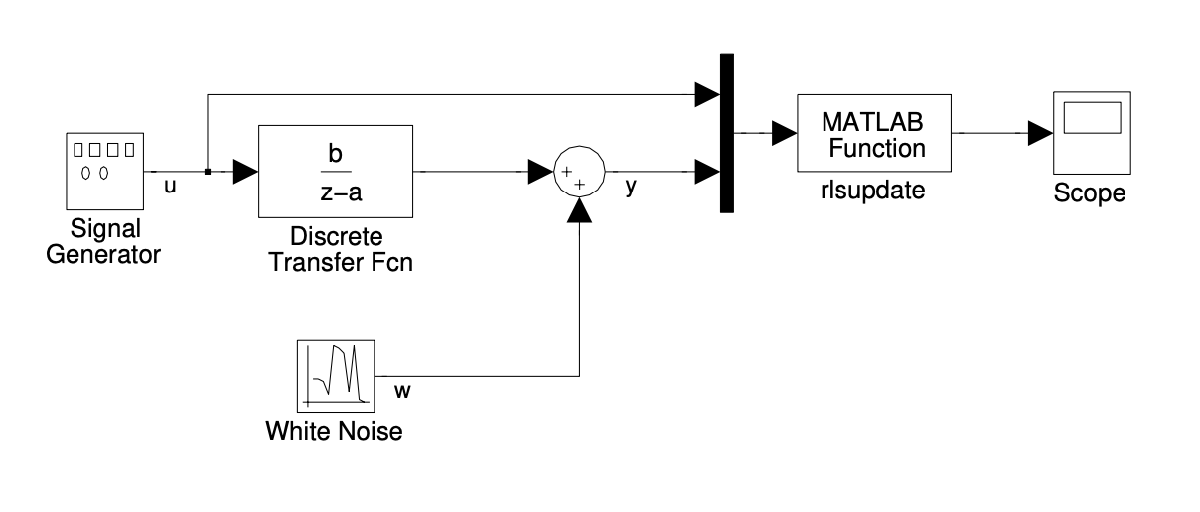

**Task 1.** Open the file `rlsmodel.mdl`

open('rlsmodel.mdl')

What Simulink block was chosen to implement the recursive least-squares?

Task1 = "Select one of the following"

**Task 2.** Now open the file `rlsupdate.m`

% Enter Code Here.

What variables have been defined as persistent? And why? Hint: Try ’help persistent'.

% Enter Code Here.

**Task 3.** Implement the recursive equations of the least squares in the file `rlsupdate.m. `Choose initial conditions $\hat{\theta }(0) = \theta _0 = [0 \quad 0]^T \ and \ P(0) = P_0 = I.$

open('rlsupdate.m')

**Task 4.** **Persistency of excitation condition. **

**(a)** Experiment with the choice of the input signal. Start with a square wave of unit amplitude and a period of $100$ samples. Repeat the experiment with various amplitudes and periods. Provide plots of the various experiments that you carried out. Function [`HW4_plots1`](matlab:open('./HW4_plots1.mlx')) is used for plotting.

- Trial 1:

clear rlsupdate % clears persistant variables from previous runs
% White Noise Parameters:
h = 0.60;    % Sample time [s]
sigma = 3;   % Variance

% Transfer Fcn Parameters:
a = 0.9;    % Pole
b = 0.1;     % Numerator

% Input Signal (Square Wave) Parameters:
uA = 1;   % Amplitude
uP = 100;  % Period [s]
 
sim('rlsmodel.mdl')
HW4_plots1(a, b, data, output);
subplot(2,1,1);
title({'Inputs and Outputs',['Square Wave Input, uA = ',num2str(uA),', uP = ',num2str(uP)]})

- Trial 2:

clear rlsupdate

% Input Signal (Square Wave) Parameters:
uA = 1;   % Amplitude
uP = 100;  % Period [s]
 
sim('rlsmodel.mdl')
HW4_plots1(a, b, data, output);
subplot(2,1,1);
title({'Inputs and Outputs',['Square Wave Input, uA = ',num2str(uA),', uP = ',num2str(uP)]})

- Trial 3:

clear rlsupdate

% Input Signal (Square Wave) Parameters:
uA = 1;   % Amplitude
uP = 100;  % Period [s]
 
sim('rlsmodel.mdl')
HW4_plots1(a, b, data, output);
subplot(2,1,1);
title({'Inputs and Outputs',['Square Wave Input, uA = ',num2str(uA),', uP = ',num2str(uP)]})

**(b)** Try with a PRBS input signal. Provide plots. Hint: Check this [link](https://www.mathworks.com/help/slcontrol/ug/prbs-input-signals.html?searchHighlight=PRBS&s_tid=srchtitle_support_results_4_PRBS) for suggestions.

clear rlsupdate
% Enter Code

**(c)** Use a Unit Pulse input signal at $t=50\ldotp$ Provide plots. Hint: Use the [Discrete Pulse Generator Block](https://www.mathworks.com/help/simulink/slref/pulsegenerator.html) or a user defined block.

clear rlsupdate
% Enter Code

**(d)**  How does the choice of the input signal affect the result? Comment on the convergence properties of the estimated parameters with respect to the input signal. 

**Task 5.** **Initial conditions.** Try different initial conditions. Do the initial conditions affect the result? Explain and provide plots of the various experiments that you carried out. Hint: Change the initial conditions in `rlsupdate.m`, then run the `rlsmodel.mdl `using default square wave input signal.

- Trial 1:

% Enter Code

- Trial 2:

% Enter Code

- Trial 3:

% Enter Code

**Task 6.** **Model structure.** In this task, $c=-0\ldotp 5$. The equation error $w\left(t\right)+\textrm{cw}\left(t-1\right)$ gives a colored noise. Show that fitting of the model in $\left(2\right)$ gives biased estimates (it is okay to show only plots). Hint: Modify `rlsmodel.mdl`, then run using default square wave input signal.

% Enter Code

**Task 7.** **Bonus.** Write a program for extended least squares estimation and show that this gives unbiased estimates of $\hat{a}, \ \hat{b} \ and \ \hat{c}.$

% Enter Code

**Task 8. Influence of forgetting factor.** Assume $a$ is time varying and introduce a forgetting factor $\lambda$ for its estimation. Test different values of $\lambda$. How does $\lambda$ affect the result? Provide plots of the various experiments that you carried out.

- Trial 1:

% Enter Code

- Trial 2:

% Enter Code

- Trial 3:

% Enter Code

## References

[1] Ljung, L., & Söderström, T. (1983). *Theory and practice of recursive identification*. MIT press.

[2] Åström, K. J.,  and Wittenmark, B. (1995). Adaptive Control. *Addison Wesley*.